# Continuous braking Thermal analysis of brake disc

This script approximates the temperature of the brake rotor after "N" applications of the brakes

Author: Luis Daniel Medina Querecuto

luisdamed@gmail.com

Date: 17/11/2019

Edit: 18/07/2023

References: 

[1] Incropera, F.,De Witt, David. "*Fundamentals of Heat and Mass Transfer, 6th Edition". *Prettice Hall. **ISBN-13:** 978-0470055540

[2] R. Limpert, Brake Design and Safety, Warrendale, PA.: Society of Automotive Engineers, Inc., 1999. **ISBN-13:** 978-1560919155

[3] B. Latour, P. Bouvier and S. Harmand, "Convective Heat Transfer on a Rotating Disk With Transverse Air Crossflow," *Journal of Heat Transfer, *vol. 133, pp. 021702-1 -10, 2011. DOI: 10.1115/1.4002603

 clc, close all

## Input data

Disc_data;
load Air_props.mat
m= 290 %car mass in kg

m = 290

I=0.3546 %Moment of inertia of the rotating parts on the wheel [kg/m2]

I = 0.3546

Vi= 70/3.6 %Initial Vehicle Speed [m/s]

Vi = 19.4444

Vf=45/3.6 %Final Vehicle Speed [m/s]

Vf = 12.5000

V_mean=(Vf+Vi)/2

V_mean = 15.9722

R_wheel=0.235 %Wheel Radius [m]

R_wheel = 0.2350

omegai=Vi/R_wheel %initial wheel angular speed [rad/s]

omegai = 82.7423

omegaf=Vf/R_wheel %Final wheel angular speed [rad/s]

omegaf = 53.1915

Decel_avg=0.5*9.81 %Average deceleration in [m/s^2]

Decel_avg = 4.9050

Brake_bias=0.5 %Portion of the total braking load applied to the axle

Brake_bias = 0.5000

tstop= (Vi-Vf)/Decel_avg %Duration of the braking maneuver [s]

tstop = 1.4158

dstop=(Vi^2-Vf^2)/(2*Decel_avg) %distance covered during braking in meters

dstop = 22.6133

tcool=5 %Cooling time between braking maneuvers [s]

tcool = 5

materials=6 %Define the number fo materials to compare. Uses Mat_properties.m

materials = 6

n= 100  %number of braking maneuvers to simulate

n = 100

Cx=1.12; %Aerodynamic drag
S_car=1; %Front surface area of the car in m2

### Average power dissipated during the single braking maneuver


$$E_k =\frac{1}{2}{\textrm{Bias}}_{\textrm{front}\;} \left(\frac{1}{2}m\left(V_i^2 -V_{f\;}^2 \right)-\frac{1}{2}\rho {\;}_{\textrm{air}\;} C_{x\;} {\textrm{SV}}_{\textrm{avg}}^2 d_{\textrm{stop}} \right)+\frac{1}{2}I\left(\omega {\;}_i^2 -\omega {\;}_f^2 \right)$$


Kinetic linear and rotational energies minus approximately the average energy dissipated by the aerodynamic drag.

Ef=0.5*Brake_bias*((m/2)*(Vi^2-Vf^2)-0.5*1.16*Cx*S_car*((Vi+Vf)/2)^2*dstop)+(I/2)*...
(omegai^2-omegaf^2) 

Ef = 7.8169e+03

Average power dissipated during the braking maneuver [W]

P_avgF=Ef/tstop; 

### Pre-allocate variables

T_disc=zeros(1,2*n);
T_film=zeros(1,2*n);
rho_air_f=zeros(1,2*n);
mu_air_f=zeros(1,2*n);
Cp_air_f=zeros(1,2*n);
k_air_f=zeros(1,2*n);
Re_f=zeros(1,2*n);
Pr_f=zeros(1,2*n);
h_conv=zeros(1,2*n);
T_disc_mat=zeros(materials,2*n);

### Evaluate the Temperature veriation for different materials

for mat=1:materials

### Thermal  cycle start

    for i=1:2*n
        if i>1 && mod(i, 2)==0
                T_disc(i)=T_disc(i-1)-Dt_cool;

        elseif mod(i, 2)==1 %Do this only for odd numbers of i
            if i==1
                %Input brake disc temperature [K].
                % Assumed or estimated value
                T_disc(i)=60+273.15;  
                
            else
                BixFo=h_conv*A_total*tcool/(rho_metal*V_disc*Cp_metal);
                
                % The temperature is increased with an exponentially smaller effect
                % with every new braking maneuver
                T_disc(i)=T_air+(1-exp(-0.5*i*BixFo))*DT_f/(1-exp(-BixFo)); 
            end
            %Air Temperature [K]
            T_air=22+273.15; 
            
            %Film Temperature [K]
            T_film(i)=(T_air+T_disc(i))/2; 

#### Air Properties vs Temperature  

            %Air density at film temperature [kg/m3]
            rho_air_f(i) = interp1(Air_props.Temp,Air_props.Density,...
                T_film(i)-273.15); 
            
            %Air Dynamic viscosity at film temperature [kg/ms]
            mu_air_f(i) = interp1(Air_props.Temp,Air_props.Dyn_Visc,...
                T_film(i)-273.15); 
            
            %Air Specific heat at film temperature [J/kgK]
            Cp_air_f(i) = interp1(Air_props.Temp,Air_props.Spec_Heat,...
                T_film(i)-273.15); 
            
            %Air Thermal conductivity at film temperature [W/mK]
            k_air_f(i) = interp1(Air_props.Temp,Air_props.Conductivity,...
                T_film(i)-273.15); 

#### Reynolds number for different flow conditions 

            %Reynolds number evaluated at film temperature
            Re_f(i)=(V_mean*r_disc*2*rho_air_f(i))/mu_air_f(i);    
            
            %Prandtl number evaluated at film temperature
            Pr_f(i)=mu_air_f(i) *Cp_air_f(i)/k_air_f(i);             

#### Heat transfer coefficient 

This expression is mentioned in reference [1]. It was determined experimentally on disc brakes for light trucks, but can also be used in other applications to a certain extent. Verified with Convection_coefficients.mlx script and  the results showed good correlation with CFD analyses at 60 km/h


$$h=0\ldotp 04\left(\frac{k_{\textrm{air}} }{D}\right){\textrm{Re}}^{0\ldotp 8}$$


             h_conv(i)=0.04*(k_air_f(i)/(2*r_disc))*Re_f(i)^0.8;

#### Load  the material properties library

             Mat_properties; 

#### Biot number verification

We determine the Biot number to verify whether assuming an uniform temperature distribution on the whole volume of the disc (lumped mass assumption) is reasonable. 

             A_total=A_edge+2*A_side+A_holes; %Total surface area of the disc
             
             %Biot number. The following equations are valid only for Bi<0.1
             Bi=h_conv*(V_disc/(A_total))/k_metal;  
                if Bi>0.09999
                   error(['The Biot number must be lower than 0.1 to assume an ' ...
                       'uniform disc temperature distribution (lumped analysis)'])
                end
        

#### Heat Transfer Disc/Pad 

The factor "p" determines the portion of heat which is transferred to the rotor body during continuous braking.

                % p=sqrt(k_metal*Cp_metal*rho_metal)*S_d/...
                % (sqrt(k_metal*Cp_metal*rho_metal)*S_d+...
                % sqrt(k_pad*Cp_pad*rho_pad)*S_p); 
                
                % This other expression is more suitable for continuous braking
                % situations, since it accounts for the heat convection
                
                %Thermal resistance of the Brake rotor
                Rd= 1/(A_total*h_conv(i)); 
                
                %Heat convection coefficient of the pad.
                hp_conv=h_conv(i); 
                
                %Thermal resistance of the pad
                Rp= 1/hp_conv+t_pad/(k_pad*S_p)+t_plate/(k_plate*S_p); 
                
                %Heat Partition Coefficient
                p=1/(1+Rd/Rp);
               



#### Calculate the temperature rise on the disc

Temperature increase of the rotor during a single stop


$$\Delta \;T=\frac{P_{\mathrm{avg}} t_{\mathrm{stop}} p}{\rho {\;}_{\mathrm{metal}} V_{\mathrm{disc}} {\mathrm{Cp}}_{\mathrm{metal}} }$$


        %Heat dissipated by convection [W]
        H_convection=(h_conv(i)*A_total)*(T_disc(i)-T_air);
        
        %Heat dissipated by radiation [W]
        H_radiation= 5.670367*10^-8*A_total*2*(T_disc(i)-T_air)^4; 
        
        % During braking, only a portion of the disc's surface is used for cooling
        f = (S_d - (2*S_p)) / S_d; % ~ 0.8

        % Compute cooling
        Dt_cool=(-H_convection-H_radiation)*(tcool)/(rho_metal*V_disc*Cp_metal);

        % Compute temperature rise
        Dt_brake = P_avgF * tstop * p / (rho_metal* V_disc * Cp_metal);
        DT_f = Dt_brake + Dt_cool * f;
        end
    end
    
   T_disc_mat(mat,:)=T_disc; %Save the results from the current material cycle
end

time=linspace(0,(tstop+tcool)*n,2*n);


figure
hold on
plot(time,T_disc_mat-273.15)


% Formatting
grid minor
set(gca, 'FontName', 'Times','fontsize',12)
xlabel('time [s]'),ylabel('Disc Temperature [°C]') 
subtitle = (['Number of braking maneuvers: ' num2str(n,'%i') ' @ ' num2str(Decel_avg/9.81, '%.1f') 'g'])

subtitle = 'Number of braking maneuvers: 100 @ 0.5g'

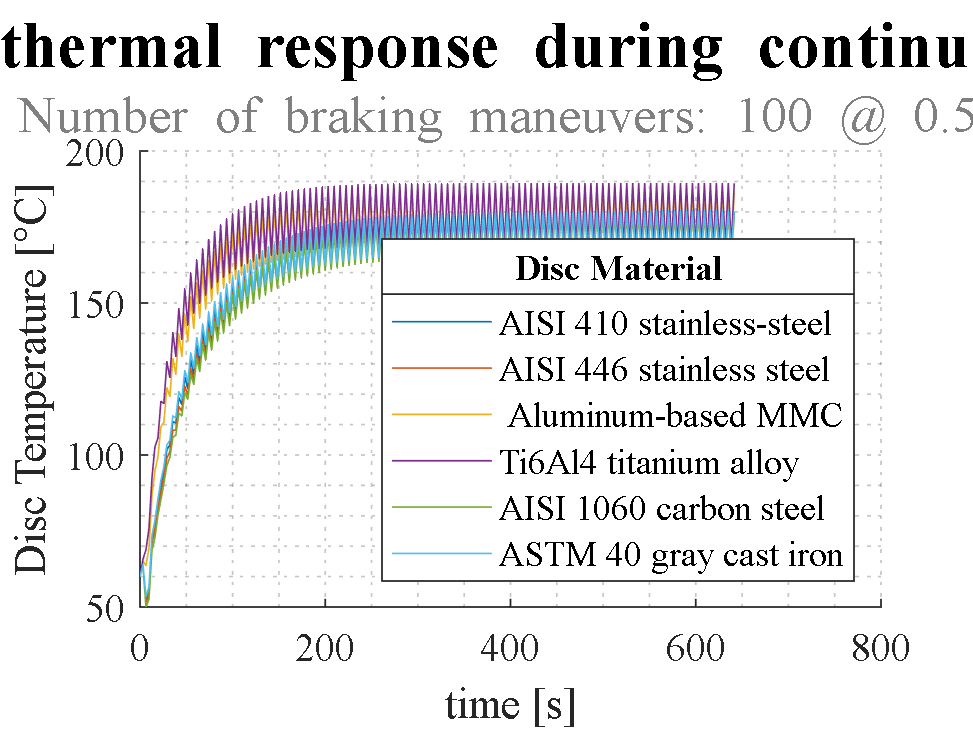

plottitle= 'Front Disc thermal response during continuous operation';
formattedText = {['\fontsize{15}\color{black}\bf' plottitle]; ['\fontsize{12}\color{gray}\rm' subtitle]};
title(formattedText)

hleg=legend('AISI 410 stainless-steel','AISI 446 stainless steel',...
        ' Aluminum-based MMC','Ti6Al4 titanium alloy','AISI 1060 carbon steel',...
        'ASTM 40 gray cast iron','location','southeast');
htitle = get(hleg,'Title');
set(htitle,'String','Disc Material')